clc
clear

POINTS = 50;

C = [3, 1; -1, -2];
min_c1= linprog(C(1, :), [0, 1; 3, -1], [3; 6], [], [], [0; 0])


Optimal solution found.



min_c1 =      0
     0


min_c2 = linprog(C(2, :), [0, 1; 3, -1], [3; 6], [], [], [0; 0])


Optimal solution found.



min_c2 =      3
     3


most_left = C*min_c1

most_left =      0
     0


most_right = C*min_c2

most_right =     12
    -9


% plot([0, 12], [0, -9], 'LineWidth', 2)
% hold on

syms f(x)
f(x) = (-3/4)*x;

select = linspace(0, 12, POINTS)

select =          0    0.2449    0.4898    0.7347    0.9796    1.2245    1.4694    1.7143    1.9592    2.2041    2.4490    2.6939    2.9388    3.1837    3.4286    3.6735    3.9184    4.1633    4.4082    4.6531    4.8980    5.1429    5.3878    5.6327    5.8776    6.1224    6.3673    6.6122    6.8571    7.1020    7.3469    7.5918    7.8367    8.0816    8.3265    8.5714    8.8163    9.0612    9.3061    9.5510    9.7959   10.0408   10.2857   10.5306   10.7755   11.0204   11.2653   11.5102   11.7551   12.0000


q = [select; double(f(select))]

q =          0    0.2449    0.4898    0.7347    0.9796    1.2245    1.4694    1.7143    1.9592    2.2041    2.4490    2.6939    2.9388    3.1837    3.4286    3.6735    3.9184    4.1633    4.4082    4.6531    4.8980    5.1429    5.3878    5.6327    5.8776    6.1224    6.3673    6.6122    6.8571    7.1020    7.3469    7.5918    7.8367    8.0816    8.3265    8.5714    8.8163    9.0612    9.3061    9.5510    9.7959   10.0408   10.2857   10.5306   10.7755   11.0204   11.2653   11.5102   11.7551   12.0000
         0   -0.1837   -0.3673   -0.5510   -0.7347   -0.9184   -1.1020   -1.2857   -1.4694   -1.6531   -1.8367   -2.0204   -2.2041   -2.3878   -2.5714   -2.7551   -2.9388   -3.1224   -3.3061   -3.4898   -3.6735   -3.8571   -4.0408   -4.2245   -4.4082   -4.5918   -4.7755   -4.9592   -5.1429   -5.3265   -5.5102   -5.6939   -5.8776   -6.0612   -6.2449   -6.4286   -6.6122   -6.7959   -6.9796   -7.1633   -7.3469   -7.5306   -7.7143   -7.8980   -8.0816   -8.2653   -8.4490   -8.6327   -8.8163   -9

A = [0, 1, 0; 3, -1, 0];
b = [3; 6];
Aeq = [-C, [-3; -4]];

front = zeros(2, POINTS);
solution = zeros(3, POINTS);
for i = 1:POINTS
    solution(:, i) = linprog([0, 0, -1], A, b, Aeq, -q(:, i), [0, 0, 0]);
    front(:,i) = q(:,i) + solution(3, i)*[-3; -4]; 
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal sol

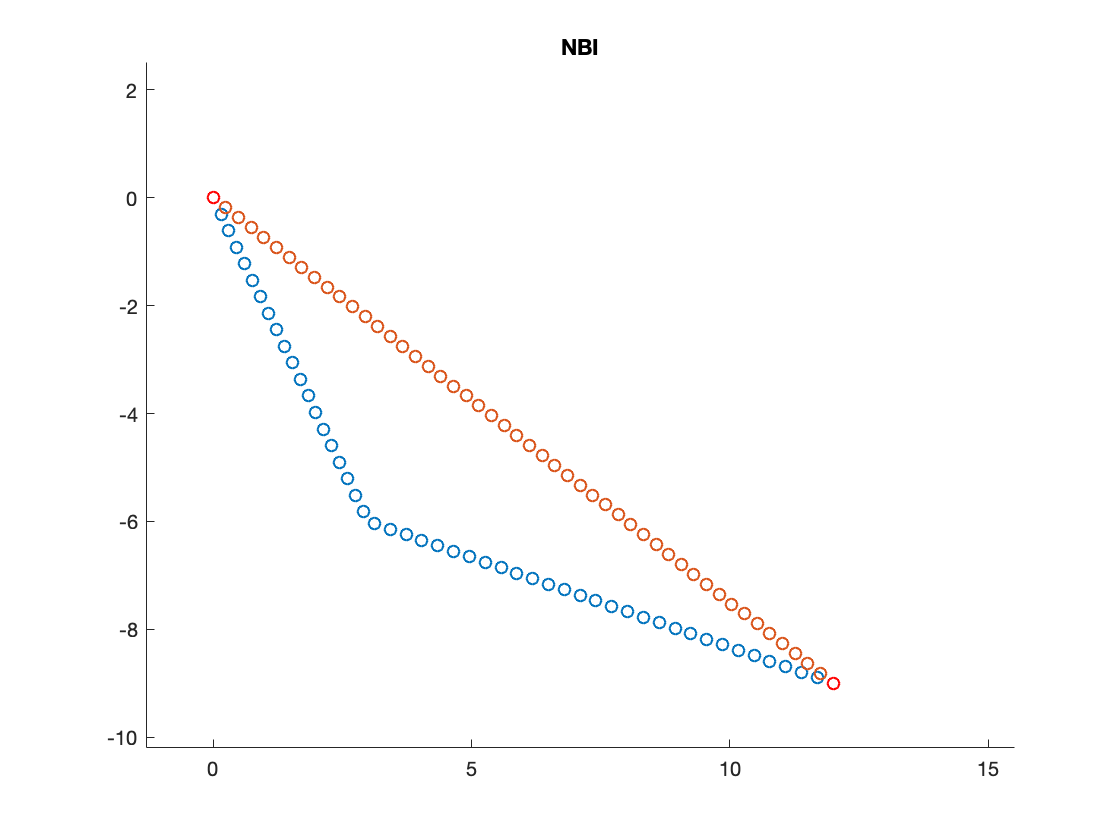

scatter(front(1,:), front(2, :))
hold on
scatter(q(1,:), q(2,:));
scatter([0, 12], [0, -9], 'red');
title('NBI');

xlim([-1.3 15.5])
ylim([-10.2 2.5])